This performs automated loopshaping on a flexible structure plant.

s = tf('s')  


s =
 
  s
 
Continuous-time transfer function.



G = 1/s^2/(s^2+3.77*s+3948);  %Build a plant model with a lightly damped mode

Now design controller to maximize crossover frequency for PM >= 40 and GM >= 6 db.

This is typical of the real world.  We have desired minimum stability margins and will push performance until we are up against them.

Let's take a look at the plant to decide on the notch filter

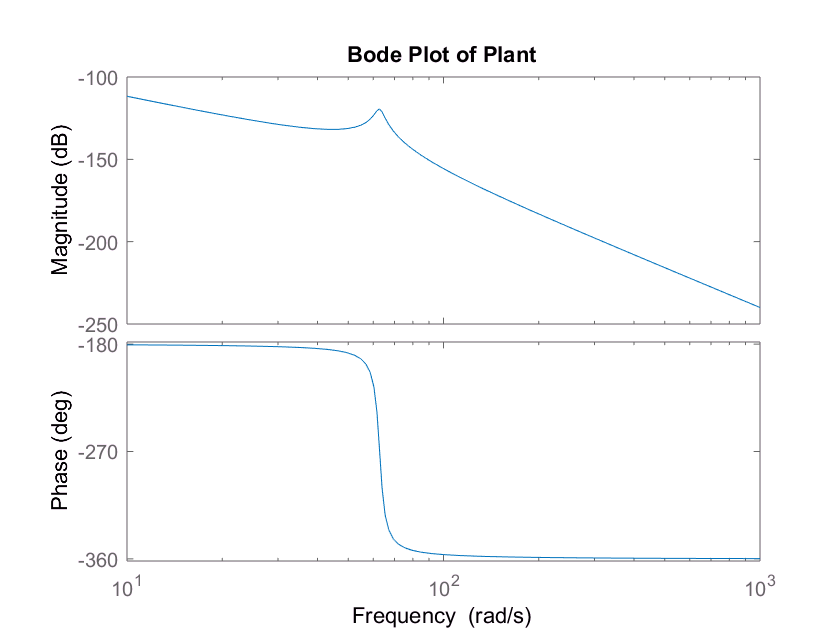

bode(G)
title('Bode Plot of Plant')

From the Bode plot, the notch peaks at 10 Hz.  Depth is about 15 dB and width is about 0.5 Hz

N = notch(15, 0.5*2*pi, 10*2*pi);

Now we need to make a lead compensator that will push our phase up to achieve the PM goal.

I know I need to back off a bit to meet my GM goal...let's look where to start checking

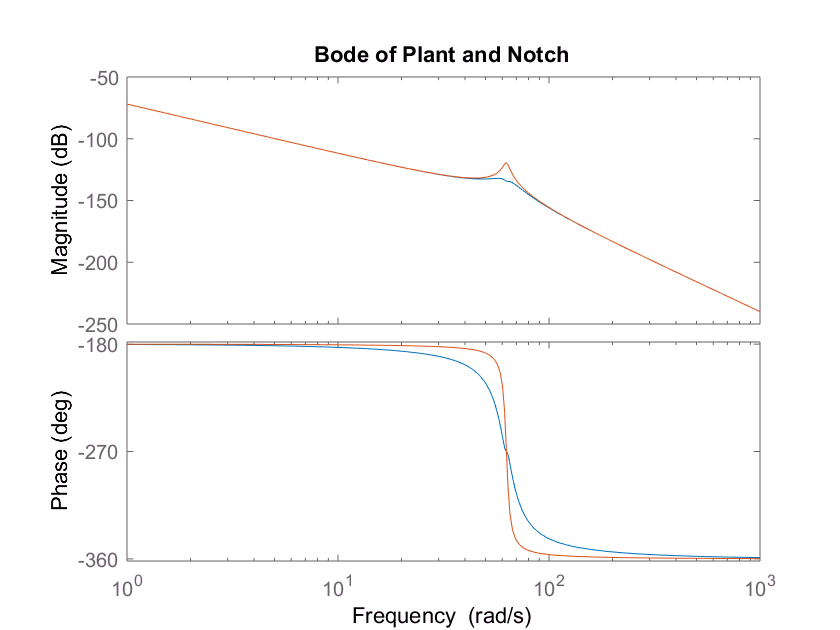

bode(G*N,G)
title('Bode of Plant and Notch')

Want to back off by about 6 dB from notch shelf - maybe start at 3.5Hz

Grab the phase of the plant at 3.5 Hz to design my lead

[mag,phase] = bode(G*N,3.5*2*pi);
Plead = -140-phase;

Now build the lead

Clead = lead(Plead,3.5*2*pi);

Now adjust magnitude to cross at 3.5 Hz

[mag,phase] = bode(G*N*Clead,3.5*2*pi);
K = 1/mag;

Test the design

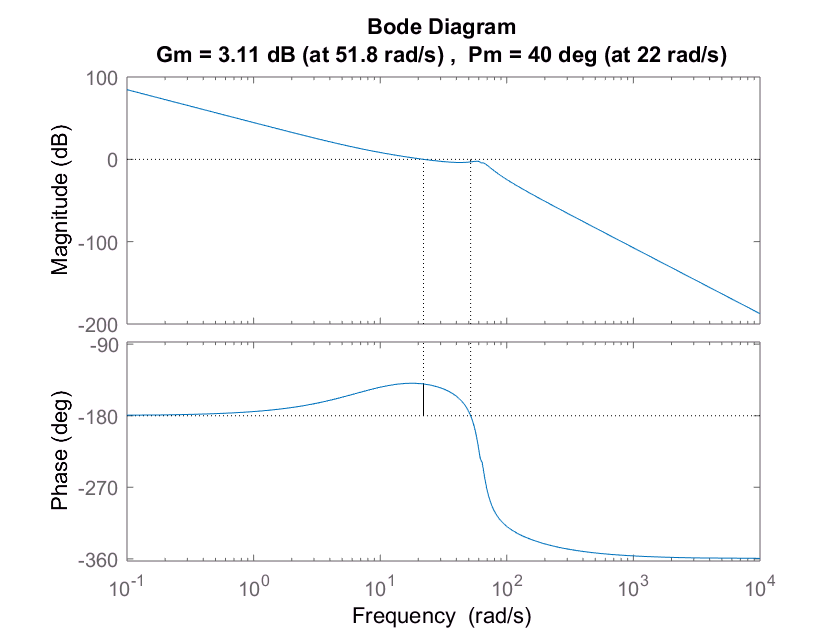

margin(K*G*N*Clead)

Ugh...not enough GM...back off on omega.  We MIGHT try to guess a new value and check, but why not automate?

Let's find the answer via some simple bisection.

wh = 3.5;
wl = 0;  %I know I can do better than 0 for bandwidth - unnecessarily conservative
w_try = wh;
w_new = 1/2*(wh+wl);
while(abs(w_new-w_try)>.001)  %Stopping criterion
    w_try = w_new;
    [mag,phase] = bode(G*N,w_try*2*pi);
    Plead = -140-phase;
    Clead = lead(Plead,w_try*2*pi);
    [mag,phase] = bode(G*N*Clead,w_try*2*pi);
    K = 1/mag;
    [Gm,Pm,Wcg,Wcp] = margin(K*G*N*Clead);  %Collect variables to test margin
    if Gm>2
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
end

Plot the final performance    

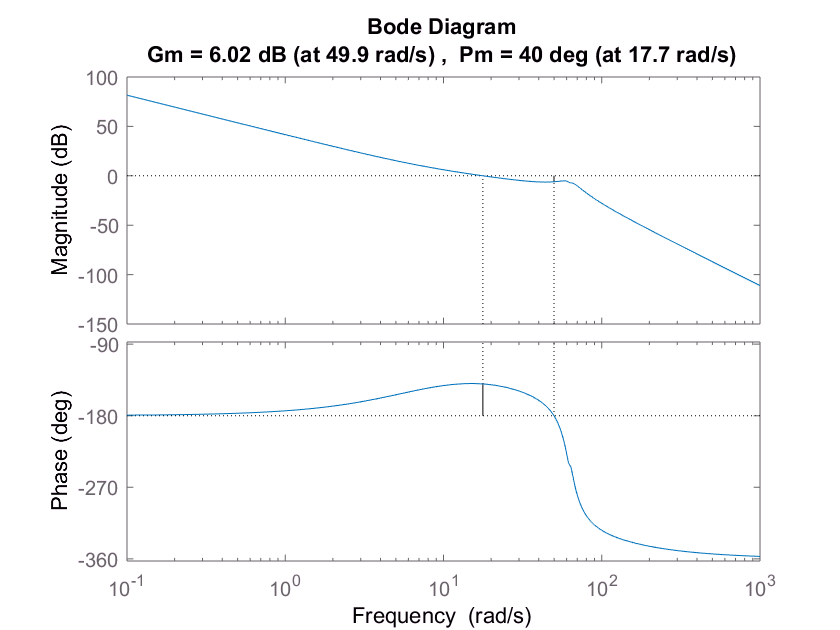

margin(K*G*N*Clead)

Find and plot the closed loop response

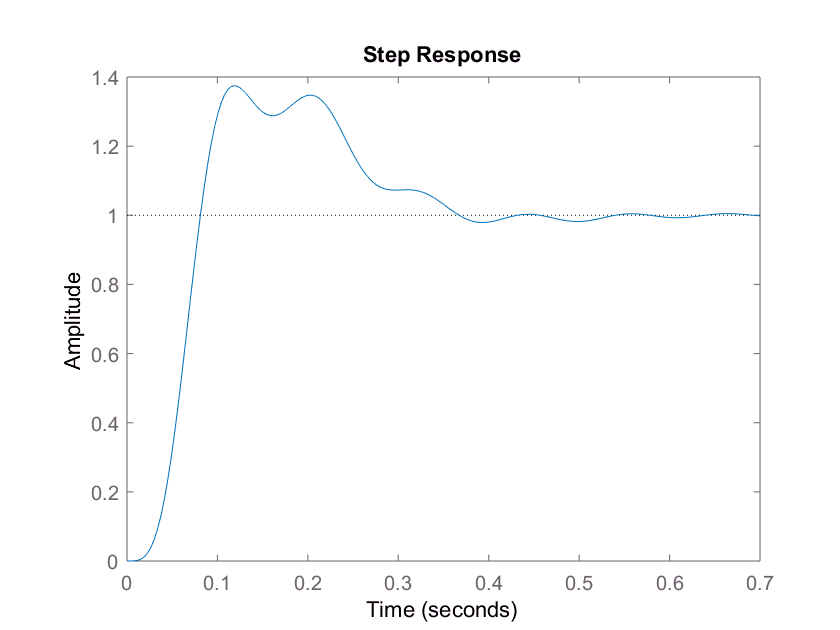

sys1 = feedback(G*K*N*Clead,1);
step(sys1)

Now look at control usage and sensitivity function.

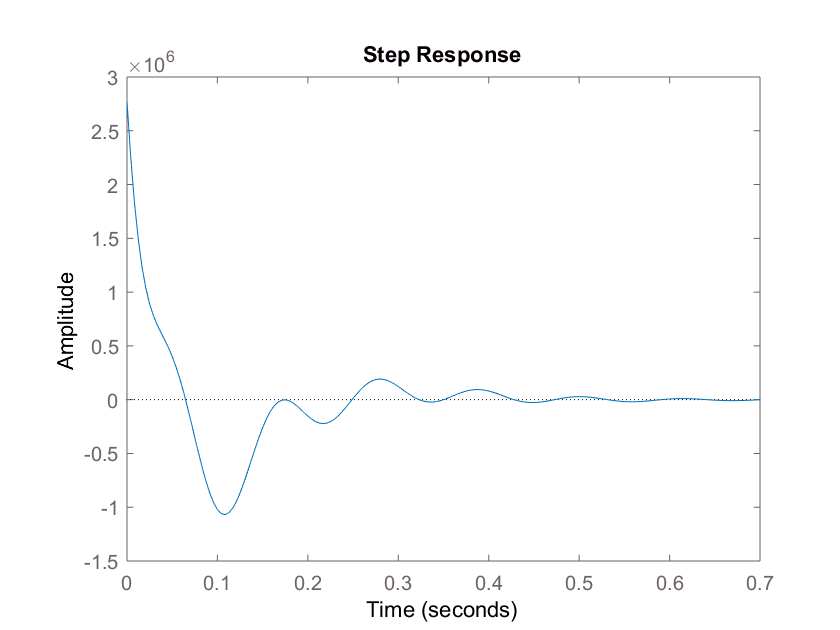

u1 = K*N*Clead*(1-sys1);
step(u1)  %The control usage

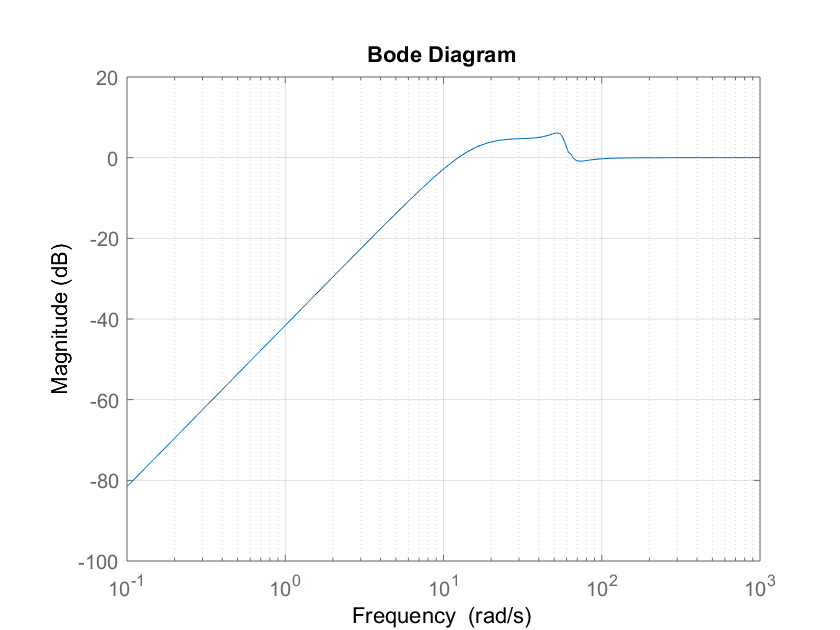

bodemag(1-sys1)  %The sensitivity function
grid